## **Assignment 2**

**A medical device needs a special machine to control the vertical position of actuator. If the transfer function of the actuator is: **

`Transfer function: X(s)/Y(s) = 1/(ms^2 + bs + k)`

**Where x is the system displacement in meter, y is the input, **

- **m is the actuator mass (10 Kg)**

- **b is the damping coefficient (20 N/m/s)**

- **k is the actuator stiffness (100 N/m)**

** It is required to design a system that can help the actuator to be positioned fast when step input is applied with minimum inertia load**

**ANSWER:**

** Define the System Parameters**

First, we need to define the parameters of the actuator.

**[ G(s) = 1 / {ms^2 + bs + k} = {1} / {10s^2 + 20s + 100} ]**

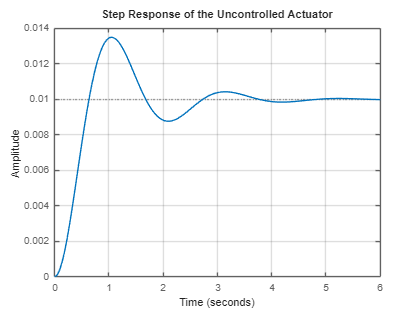

% Define system parameters
m = 10; % kg
b = 20; % N/m/s
k = 100; % N/m

% Define the transfer function
num = 1; % Numerator
den = [m, b, k]; % Denominator
G = tf(num, den);

% Step response for the uncontroller system
figure;
step(G);
title('Step Response of the Uncontrolled Actuator');
grid on;

**Design a P Controller**

A proportional controller can be designed by tuning the gain ( K_p ).

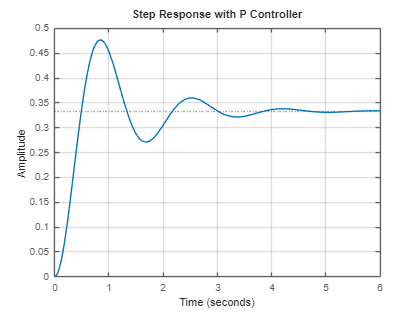

% P Controller
Kp = 50; % Proportional gain
C_p = pid(Kp);

% Closed-loop system
sys_cl_p = feedback(C_p * G, 1);

% Step response of the P controller
figure;
step(sys_cl_p);
title('Step Response with P Controller');
grid on;

 **Design a PI Controller**

For a PI controller, we will set the proportional and integral gains

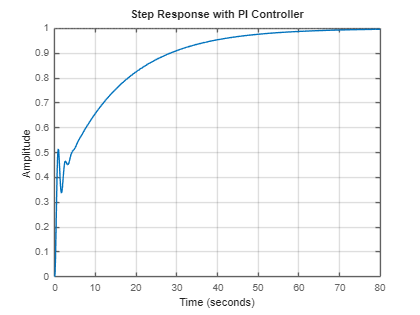

% PI Controller
Kp = 50; % Proportional gain
Ki = 10; % Integral gain
C_pi = pid(Kp, Ki);

% Closed-loop system
sys_cl_pi = feedback(C_pi * G, 1);

% Step response of the PI controller
figure;
step(sys_cl_pi);
title('Step Response with PI Controller');
grid on;

**Design a PD Controller**

We will set the proportional and derivative gains for the PD controller.

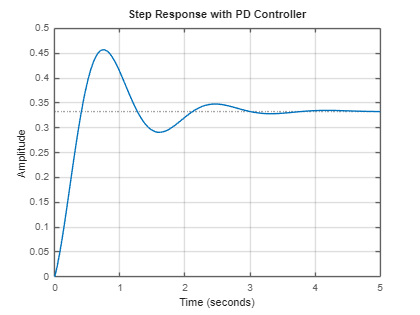

% PD Controller
Kp = 50; % Proportional gain
Kd = 5; % Derivative gain
C_pd = pid(Kp, 0, Kd);

% Closed-loop system
sys_cl_pd = feedback(C_pd * G, 1);

% Step response of the PD controller
figure;
step(sys_cl_pd);
title('Step Response with PD Controller');
grid on;

**Design a PID Controller**

Finally, combine all three gains for the PID controller.

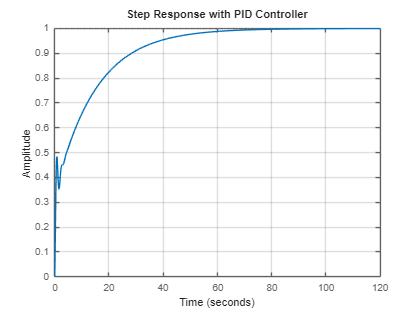

% PID Controller
Kp = 50; % Proportional gain
Ki = 10; % Integral gain
Kd = 5; % Derivative gain
C_pid = pid(Kp, Ki, Kd);

% Closed-loop system
sys_cl_pid = feedback(C_pid * G, 1);

% Step response of the PID controller
figure;
step(sys_cl_pid);
title('Step Response with PID Controller');
grid on;

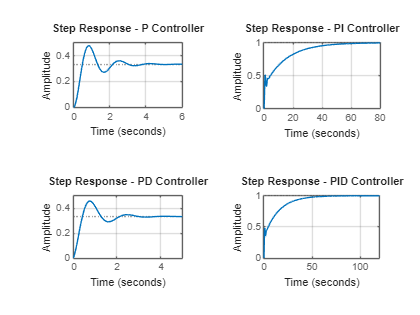

% Step response for P Controller
figure;
subplot(2,2,1);
step(sys_cl_p);
title('Step Response - P Controller');
grid on;

% Step response for PI Controller
subplot(2,2,2);
step(sys_cl_pi);
title('Step Response - PI Controller');
grid on;

% Step response for PD Controller
subplot(2,2,3);
step(sys_cl_pd);
title('Step Response - PD Controller');
grid on;

% Step response for PID Controller
subplot(2,2,4);
step(sys_cl_pid);
title('Step Response - PID Controller');
grid on;

To analyze the system response for each controller type (P, PI, PD, and PID) and determine whether the system is underdamped, overdamped, or critically damped, we will evaluate the step response characteristics. In control systems, these terms describe the behavior of the system in terms of its overshoot and settling time.

- **Underdamped**: The system oscillates before settling at the desired value. Typically, this occurs when there is significant overshoot (greater than 0%).

- **Critically Damped**: The system returns to its equilibrium position as quickly as possible without oscillating. It has the fastest response time without overshoot.

- **Overdamped**: The system returns to equilibrium slowly without oscillating. This usually results in a longer settling time.

Here we make a function to anaylyze the damping characterstics .

% Define system parameters
m = 10; % kg
b = 20; % N/(m/s)
k = 100; % N/m

% Define transfer function
num = 1; % numerator
den = [m, b, k]; % denominator
G = tf(num, den);

% P Controller
Kp = 50; % Proportional gain
C_p = pid(Kp);
sys_cl_p = feedback(C_p * G, 1);
figure;
step(sys_cl_p);
title('Step Response with P Controller');
grid on;

[y_p, t_p] = step(sys_cl_p);
analyze_damping(y_p, t_p, 'P Controller');

P Controller:
  Percent Overshoot: 42.77%
  Settling Time: 3.66 seconds
  System is Underdamped




% PI Controller
Kp = 50; % Proportional gain
Ki = 10; % Integral gain
C_pi = pid(Kp, Ki);
sys_cl_pi = feedback(C_pi * G, 1);
figure;
step(sys_cl_pi);
title('Step Response with PI Controller');
grid on;

[y_pi, t_pi] = step(sys_cl_pi);
analyze_damping(y_pi, t_pi, 'PI Controller');

PI Controller:
  Percent Overshoot: 0.00%
  Settling Time: 49.62 seconds
  System is Overdamped




% PD Controller
Kp = 50; % Proportional gain
Kd = 5; % Derivative gain
C_pd = pid(Kp, 0, Kd);
sys_cl_pd = feedback(C_pd * G, 1);
figure;
step(sys_cl_pd);
title('Step Response with PD Controller');
grid on;

[y_pd, t_pd] = step(sys_cl_pd);
analyze_damping(y_pd, t_pd, 'PD Controller');

PD Controller:
  Percent Overshoot: 37.09%
  Settling Time: 2.78 seconds
  System is Underdamped




% PID Controller
Kp = 50; % Proportional gain
Ki = 10; % Integral gain
Kd = 5; % Derivative gain
C_pid = pid(Kp, Ki, Kd);
sys_cl_pid = feedback(C_pid * G, 1);
figure;
step(sys_cl_pid);
title('Step Response with PID Controller');
grid on;

[y_pid, t_pid] = step(sys_cl_pid);
analyze_damping(y_pid, t_pid, 'PID Controller');

PID Controller:
  Percent Overshoot: 0.00%
  Settling Time: 51.95 seconds
  System is Overdamped




% Function to analyze damping characteristics
function analyze_damping(y, t, controller_name)
    % Calculate the overshoot and settling time
    info = stepinfo(y, t);
    
    % Extract overshoot and settling time
    overshoot = info.Overshoot;
    settling_time = info.SettlingTime;

    fprintf('%s:\n', controller_name);
    fprintf('  Percent Overshoot: %.2f%%\n', overshoot);
    fprintf('  Settling Time: %.2f seconds\n', settling_time);
    
    % Determine damping type based on overshoot
    if overshoot > 0
        fprintf('  System is Underdamped\n\n');
    elseif overshoot == 0 && settling_time < 2
        fprintf('  System is Critically Damped\n\n');
    else
        fprintf('  System is Overdamped\n\n');
    end
end

To effectively tune the controller gains (Kp, Ki, Kd) and  to observe the system response, we can do this. This involves creating a loop that adjusts the gains, performs simulations, and visualizes the results

Define a Tuning Strategy

- **Gain Range**: Define a reasonable range for each controller gain (Kp, Ki, Kd).

- **Incremental Steps**: Decide on the incremental steps for tuning each gain.

- **Performance Criteria**: Set performance criteria for evaluating the system response, such as overshoot, settling time, and steady-state error.

We'll implement a loop through different values of Kp, Ki, and Kd while observing the system response for each combination. The results will be stored and analyzed to identify the best performing parameters.

% Define system parameters
m = 10; % kg
b = 20; % N/(m/s)
k = 100; % N/m

% Define transfer function
num = 1; % numerator
den = [m, b, k]; % denominator
G = tf(num, den);

% Define ranges for tuning
Kp_values = 0:5:100; % Proportional gain range
Ki_values = 0:1:20;  % Integral gain range
Kd_values = 0:1:20;  % Derivative gain range

% Initialize best performance metrics
best_overshoot = inf;
best_settling_time = inf;
best_params = [0, 0, 0];

% Loop through each gain combination
for Kp = Kp_values
    for Ki = Ki_values
        for Kd = Kd_values
            % Create PID Controller
            C = pid(Kp, Ki, Kd);
            % Create Closed-loop System
            sys_cl = feedback(C * G, 1);
            
            % Calculate step response
            info = stepinfo(sys_cl);
            
            % Check performance criteria
            if info.Overshoot < best_overshoot || (info.Overshoot == best_overshoot && info.SettlingTime < best_settling_time)
                best_overshoot = info.Overshoot;
                best_settling_time = info.SettlingTime;
                best_params = [Kp, Ki, Kd];
            end
            
            % Optional: Display progress
            fprintf('Kp: %d, Ki: %d, Kd: %d => Overshoot: %.2f%%, Settling Time: %.2f seconds\n', Kp, Ki, Kd, info.Overshoot, info.SettlingTime);
        end
    end
end

Kp: 0, Ki: 0, Kd: 0 => Overshoot: Inf%, Settling Time: 0.00 seconds
Kp: 0, Ki: 0, Kd: 1 => Overshoot: Inf%, Settling Time: NaN seconds
Kp: 0, Ki: 0, Kd: 2 => Overshoot: Inf%, Settling Time: NaN seconds
Kp: 0, Ki: 0, Kd: 3 => Overshoot: Inf%, Settling Time: NaN seconds
Kp: 0, Ki: 0, Kd: 4 => Overshoot: Inf%, Settling Time: NaN seconds
Kp: 0, Ki: 0, Kd: 5 => Overshoot: Inf%, Settling Time: NaN seconds
Kp: 0, Ki: 0, Kd: 6 => Overshoot: Inf%, Settling Time: NaN seconds
Kp: 0, Ki: 0, Kd: 7 => Overshoot: Inf%, Settling Time: NaN seconds
Kp: 0, Ki: 0, Kd: 8 => Overshoot: Inf%, Settling Time: NaN seconds
Kp: 0, Ki: 0, Kd: 9 => Overshoot: Inf%, Settling Time: NaN seconds
Kp: 0, Ki: 0, Kd: 10 => Overshoot: Inf%, Settling Time: NaN seconds
Kp: 0, Ki: 0, Kd: 11 => Overshoot: Inf%, Settling Time: NaN seconds
Kp: 0, Ki: 0, Kd: 12 => Overshoot: Inf%, Settling Time: NaN seconds
Kp: 0, Ki: 0, Kd: 13 => Overshoot: Inf%, Settling Time: NaN seconds
Kp: 0, Ki: 0, Kd: 14 => Overshoot: Inf%, Settling Time: N


% Display best parameters found
fprintf('Best Parameters:\n Kp: %.2f, Ki: %.2f, Kd: %.2f\n', best_params(1), best_params(2), best_params(3));

Best Parameters:
 Kp: 0.00, Ki: 20.00, Kd: 20.00


fprintf('Best Performance:\n Overshoot: %.2f%%, Settling Time: %.2f seconds\n', best_overshoot, best_settling_time);

Best Performance:
 Overshoot: 0.00%, Settling Time: 18.57 seconds


**Observing the System Response**

To visualize the system response for the best parameters found

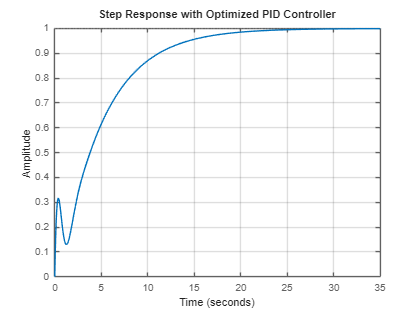

% Final simulation with best parameters
C_best = pid(best_params(1), best_params(2), best_params(3));
sys_cl_best = feedback(C_best * G, 1);
figure;
step(sys_cl_best);
title('Step Response with Optimized PID Controller');
grid on;

seeing open loop response

% Model Equation: mx'' + cx' + kx = F
% Transfer Function (Laplace Transform of model): X(s)/F(s) = 1/(ms^2 + cs + k) 
% m = mass of block, c = damping constant, k = spring constant
% F is the applied force
% x is the resulting displacement of the block

m = 10; % kg
b = 20; % N/m/s
k = 100; % N/m

% Open-Loop Response
s = tf('s');
P = 1/(m*s^2 + c*s + k) % Transfer function


P =
 
           1
  -------------------
  10 s^2 + 20 s + 100
 
Continuous-time transfer function.
Model Properties


step(P)

% PID Control Values 
Kp = 50;
Kd = 10;
Ki = 5;

% Time-step 0.01 s
t  = 0:0.01:5;

hold on
% Only Proportional Control
C1  = pid(Kp,0,0)


C1 =
 
  Kp = 50
 
P-only controller.
Model Properties


T1   = feedback(C1*P,1) % Transfer function with P-only controller


T1 =
 
          50
  -------------------
  10 s^2 + 20 s + 150
 
Continuous-time transfer function.
Model Properties


step(T1,t)


% Only Integral Control
C2  = pid(0,Ki,0)


C2 =
 
        1 
  Ki * ---
        s 

  with Ki = 5
 
Continuous-time I-only controller.
Model Properties


T2   = feedback(C2*P,1) % Transfer function with P-only controller


T2 =
 
               5
  ---------------------------
  10 s^3 + 20 s^2 + 100 s + 5
 
Continuous-time transfer function.
Model Properties


step(T2,t)

% Only Derivative Control
C3  = pid(0,0,Kd)


C3 =
 
             
  Kp + Kd * s
             

  with Kp = 0, Kd = 10
 
Continuous-time PD controller in parallel form.
Model Properties


T3   = feedback(C3*P,1) % Transfer function with P-only controller


T3 =
 
         10 s
  -------------------
  10 s^2 + 30 s + 100
 
Continuous-time transfer function.
Model Properties


step(T3,t)

% Proportional-Derivative Control
C4  = pid(Kp,0,Kd)


C4 =
 
             
  Kp + Kd * s
             

  with Kp = 50, Kd = 10
 
Continuous-time PD controller in parallel form.
Model Properties


T4  = feedback(C4*P,1)


T4 =
 
       10 s + 50
  -------------------
  10 s^2 + 30 s + 150
 
Continuous-time transfer function.
Model Properties


step(T4,t)

% Proportional-Integral Control
C5  = pid(Kp,Ki,0)


C5 =
 
             1 
  Kp + Ki * ---
             s 

  with Kp = 50, Ki = 5
 
Continuous-time PI controller in parallel form.
Model Properties


T5  = feedback(C5*P,1)


T5 =
 
           50 s + 5
  ---------------------------
  10 s^3 + 20 s^2 + 150 s + 5
 
Continuous-time transfer function.
Model Properties


step(T5,t)

% Proportional-Integral-Derivative Control
C6  = pid(Kp,Ki,Kd)


C6 =
 
             1          
  Kp + Ki * --- + Kd * s
             s          

  with Kp = 50, Ki = 5, Kd = 10
 
Continuous-time PID controller in parallel form.
Model Properties


T6  = feedback(C6*P,1)


T6 =
 
       10 s^2 + 50 s + 5
  ---------------------------
  10 s^3 + 30 s^2 + 150 s + 5
 
Continuous-time transfer function.
Model Properties


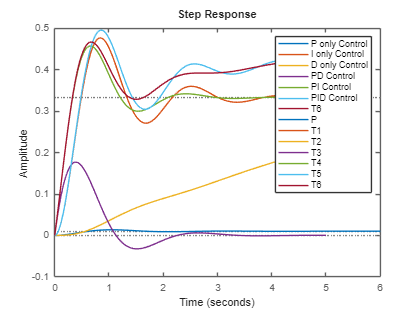

step(T6,t)

legend('P only Control','I only Control','D only Control','PD Control','PI Control','PID Control')